# `Activity 2.1`

### `Load Audio Data`

fs = 44100;
[y1,~] = audioread("andean-flute-theme-low_fybeqsnu1.mp3");
[y2,~] = audioread("zo_-pripyati-gitara.mp3");
[y3,~] = audioread("cirk-barabannaya-drob-i-marsh_-silachi.mp3");
[y4,~] = audioread("jamaican-piano_mytjcqbd.mp3");
[y5,~] = audioread("violin-trill_mk15cun_.mp3");
[y6,~] = audioread("z_uk-truba.mp3");

### `Create Samples`

n_samples = 1

n_samples = 1

range = 2*fs

range = 88200

start = 2*fs;
flute = create_sample_data(y1(:,1),n_samples,range,start);
gitar = create_sample_data(y2(:,1),n_samples,range,start);
drum  = create_sample_data(y3(:,1),n_samples,range,start);
piano = create_sample_data(y4(:,1),n_samples,range,start);
violin = create_sample_data(y5(:,1),n_samples,range,start);
trumpt = create_sample_data(y6(:,1),n_samples,range,start);

## `Correlation of Flute with Other Instruments`

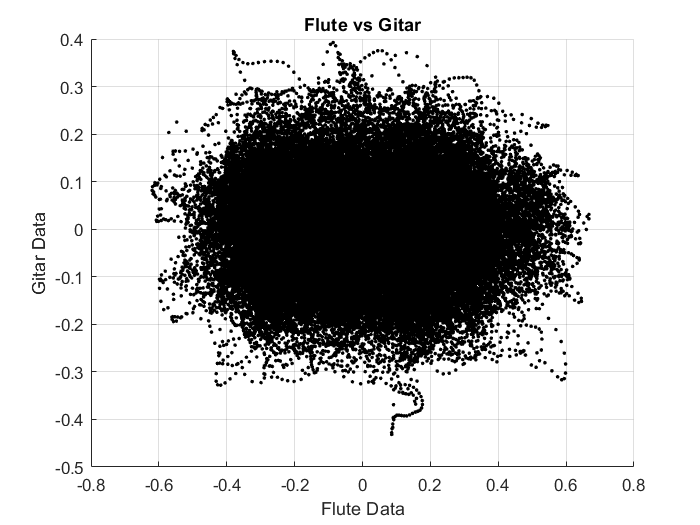

figure()
scatter(flute(:,1),gitar(:,1),5,'black',"filled")
xlabel('Flute Data')
ylabel('Gitar Data')
title('Flute vs Gitar')
grid on

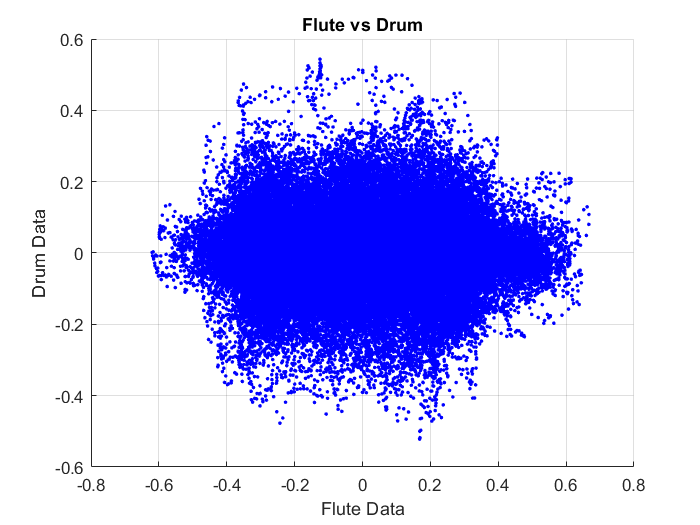


figure()
scatter(flute(:,1),drum(:,1),5,'blue',"filled")
xlabel('Flute Data')
ylabel('Drum Data')
title('Flute vs Drum')
grid on

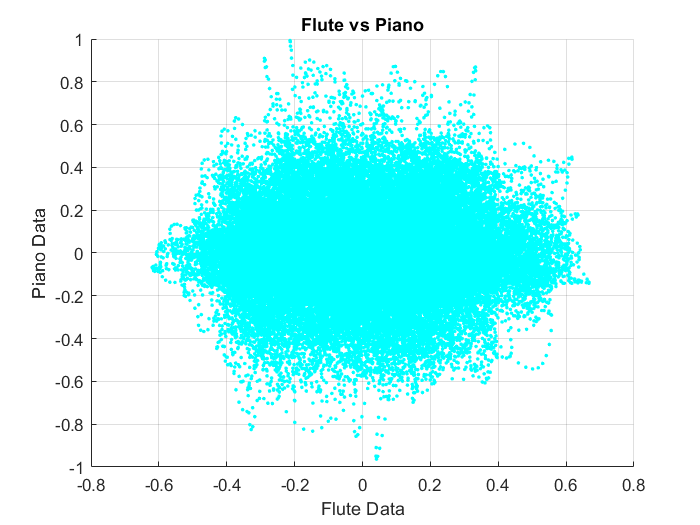


figure()
scatter(flute(:,1),piano(:,1),5,'cyan',"filled")
xlabel('Flute Data')
ylabel('Piano Data')
title('Flute vs Piano')
grid on

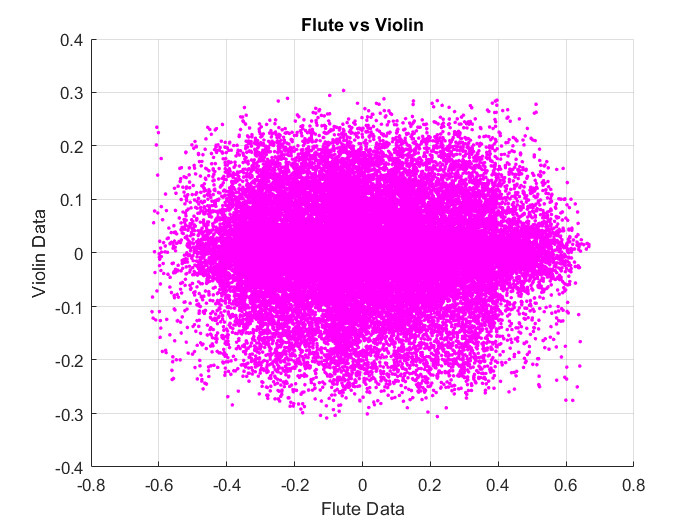



figure()
scatter(flute(:,1),violin(:,1),5,'magenta',"filled")
xlabel('Flute Data')
ylabel('Violin Data')
title('Flute vs Violin')
grid on

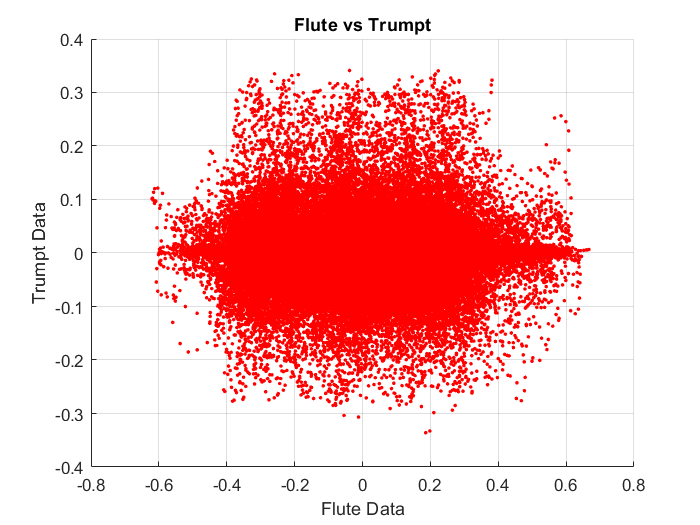


figure()
scatter(flute(:,1),trumpt(:,1),5,'red',"filled")
xlabel('Flute Data')
ylabel('Trumpt Data')
title('Flute vs Trumpt')
grid on

function sample = create_sample_data(data_array,n_samples,range,start)
    sample = zeros(range,n_samples);
    for i=1:n_samples
        range_sample = (i-1)*range+1 : i*range;
        range_data = ((i-1)*range+1)+start : (i*range)+start;
        sample(range_sample) = data_array(range_data);
    end
end

